# **FEECONS Term Project**

**DAYRIT, Bettina Gaille H.**

**GUEVARRA, Gia Kyla S.**

**RODRIGUEZ, Mariah Venice A.**

**SABINO, Cleajane Y.**

**SULIT, Keane Dwight A.**

## BLOCK DIAGRAM REFERNCES

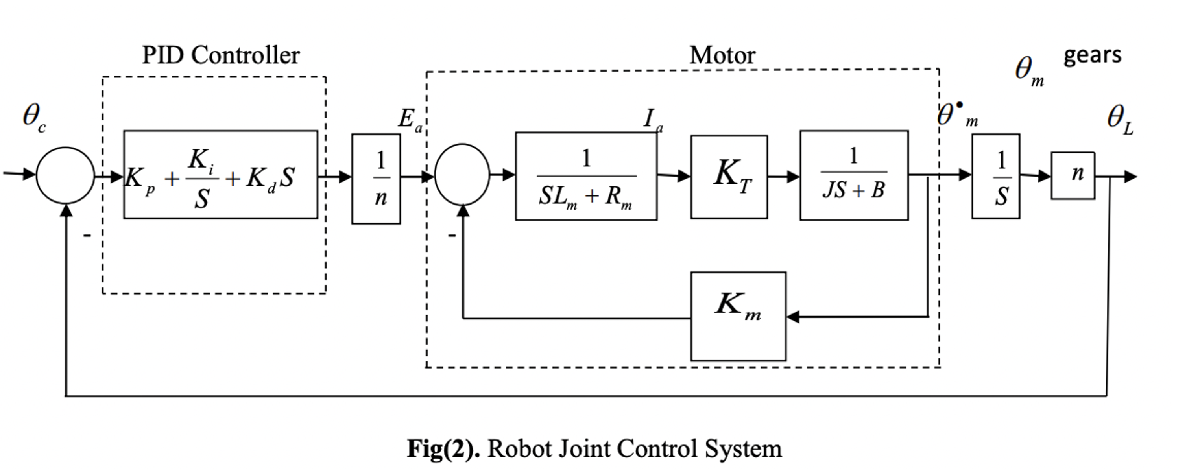

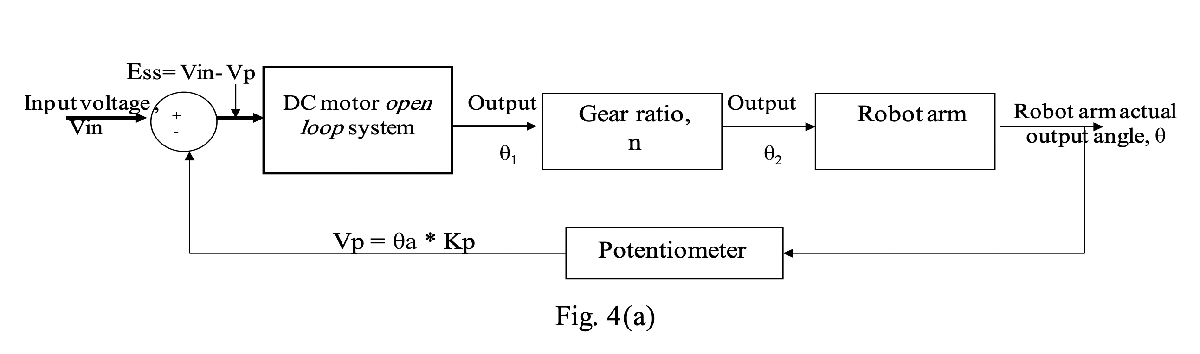

## POSITION CONTROL (ANGULAR POSITION OUTPUT)

### TRANSFER FUNCTION

The transfer function is given by the following (motor and arm)

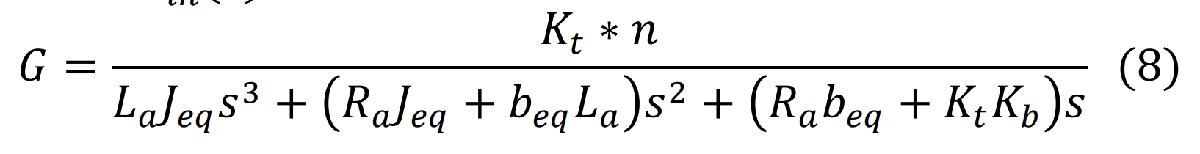

clc, clear all, close all

% Declaring nominal values of the system
J = 0.05; 
b = 0.09;
Kb = 0.020;
Kt = 0.022;
Ra = 2; % in ohms
La = 0.03; % in Henry
V = 12; % in volts
M= 10; 
b_arm= 0.03;
L = 0.5; % in m
n= 1;

% calculating Jload given by the formula, (ml^2)/12
Jload= (M*L^2)/12;

% calculating equivalent values
beq= b_arm + b*n;
Jeq= J + Jload*n;

V_max = input(' Enter maximum allowed voltage , V max : ');
Angle_max = input( 'Enter maximum allowed angle for robot arm : ');

% determining the transfer function [OPEN LOOP] 
num = [Kt*n];
den=[(La*Jeq) (Ra*Jeq+beq*La) (Ra*beq+Kt*Kb) 0];
disp('Robot arm open loop transfer function, Angle/Volt: ')

Robot arm open loop transfer function, Angle/Volt: 


Gs_OLTF =tf(num,den)

Gs_OLTF =
 
                 0.022
  -----------------------------------
  0.00775 s^3 + 0.5203 s^2 + 0.2404 s
 
Continuous-time transfer function.



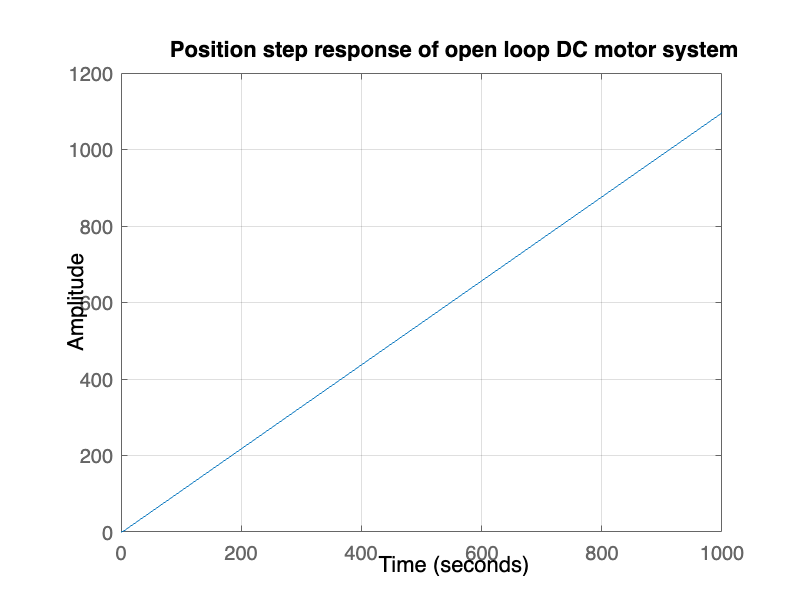

Gs_OLTFa = V*Gs_OLTF;
step(Gs_OLTFa); title('Position step response of open loop DC motor system'); grid on


% Sensor modelling, Km/Potentiometer
Km =V_max/Angle_max; % potentiometer
Gs_CLTF= feedback(Gs_OLTF,(Km/n))

Gs_CLTF =
 
                     0.022
  --------------------------------------------
  0.00775 s^3 + 0.5203 s^2 + 0.2404 s + 0.0022
 
Continuous-time transfer function.



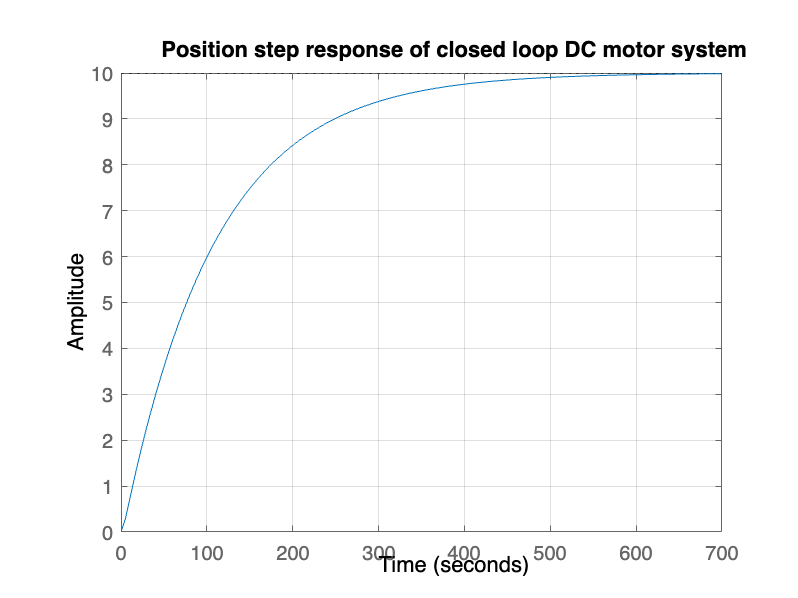

step(Gs_CLTF); title('Position step response of closed loop DC motor system'); grid on


% Getting Initial Time Responses
info_mtr= stepinfo(Gs_CLTF)

info_mtr = struct with fields:
         RiseTime: 235.3006
    TransientTime: 421.1685
     SettlingTime: 421.1685
      SettlingMin: 9.0249
      SettlingMax: 9.9933
        Overshoot: 0
       Undershoot: 0
             Peak: 9.9933
         PeakTime: 784.0838


% getting steady-state error
[out, t]= step(Gs_CLTF);
SP= 1;
error= abs(SP-out(end))

error = 8.9692

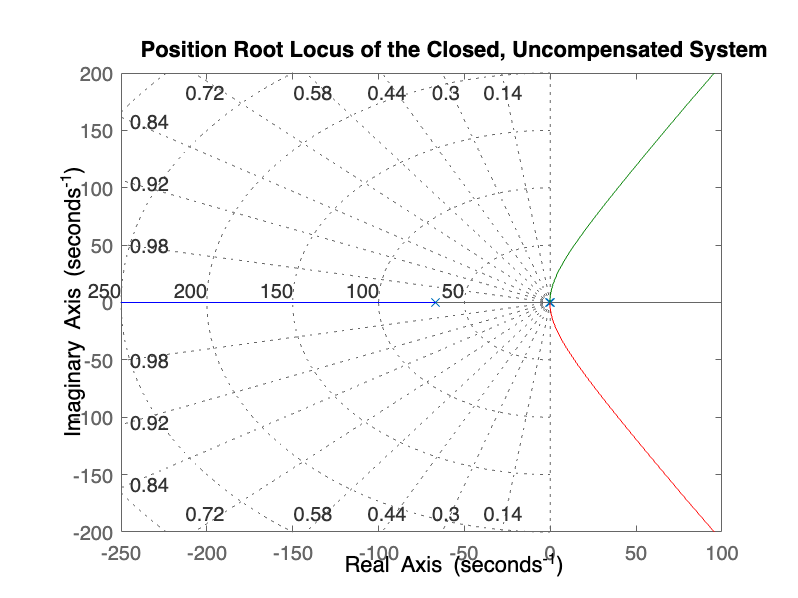


% root locus visualizations
rlocus(Gs_CLTF); grid on; title ('Position Root Locus of the Closed, Uncompensated System')


dena= [0.00775 0.5203 0.2404 0.0022]; % getting the precise value of the poles
poles= roots(dena)

poles =   -66.6703
   -0.4559
   -0.0093


From the given step response info: 

- Settling Time= 421.1685 ... does not satisfy the condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 1%)

- Steady-state error= 8.9692 ... does not satisfy the condition (<=1%)

== **VISUALIZATION**

Control System Designer

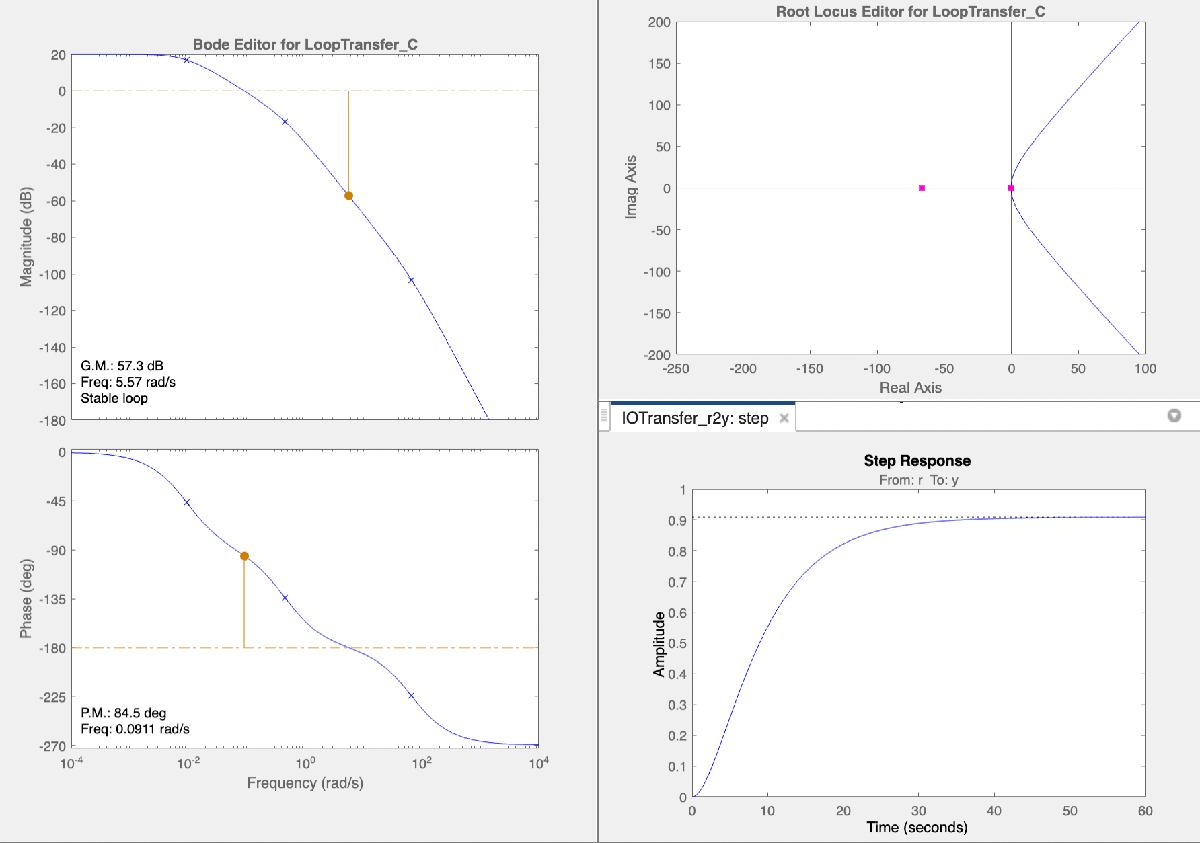

### DETERMINING THE DESIRED POLES

== **DESIGN CRITERIA:**

- Settling Time (Ts) <= 1 second

- % Overshoot <= 1%

- Steady State Error = 1

% ... from the given design criteria:
Ts=1;
PO=0.01;
SSE=1;   

zeta= sqrt(log(PO)^2 /(pi^2 + log(PO)^2)) %Damping ratio

zeta = 0.8261

Wn=4/(Ts*zeta) % Natural frequency 

Wn = 4.8421

Incorporating the parameters, the given transfer function is now:

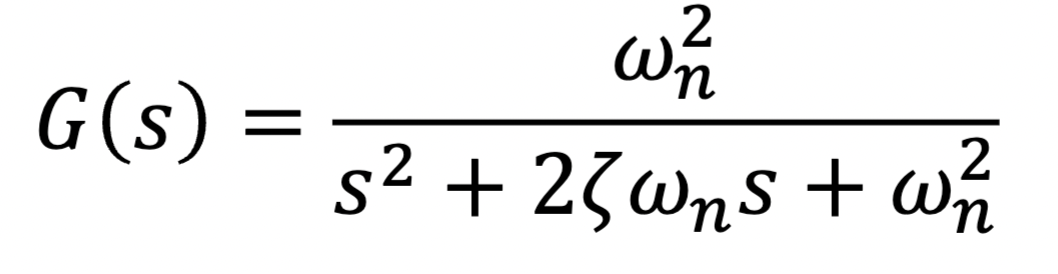

% Computing for the desired poles:
num1= [(Wn)^2];
den1= [1 2*zeta*Wn (Wn)^2];
poles= roots(den1)

poles =   -4.0000 + 2.7288i
  -4.0000 - 2.7288i


**== COMMENT **

Therefore, $S_{1,2\;} =-4\pm 2\ldotp 7288j$ are the desired poles. 

### DESIGNING THE COMPENSATORS  

#### Designing a LEAD Compensator 

% From the poles in the system and shown in the root locus, place a zero
% close to the right most pole, P3= =-0.0093

zlead= 0.009125% approximate (trial and error) value

zlead = 0.0091

Calculations (formula) for Plead:


$$\Sigma \theta_z -\Sigma \theta_p =-180$$


θ4 - (θ1+θ2+θ3+θ5)= -180

Calculations (formula) for the overall gain, 


$$K_{\textrm{overall}} =\frac{\Pi \;\textrm{pole}\;\textrm{lengths}\;}{\Pi \;\textrm{zero}\;\textrm{lengths}\;}=\;\frac{\textrm{L1}\;\textrm{L2}\;\textrm{L3}\;\textrm{L5}}{\textrm{L4}}$$
 

% calculating for the angles
theta1= 180- rad2deg(atan(2.7288/(4-0.4559)))

theta1 = 142.4053

theta2= rad2deg(atan(2.7288/(66.6703-4)))

theta2 = 2.4932

theta3= 180-rad2deg(atan(2.7288/(4-0.0093)))

theta3 = 145.6361

theta4= 180- rad2deg(atan(2.7288/(4-0.009125)))

theta4 = 145.6372

syms x plead
theta5= rad2deg(atan(2.7288/(plead-4)))

$$theta5 = \frac{180\,\mathrm{atan}\left(\frac{3411}{1250\,\left(\mathrm{plead}-4\right)}\right)}{\pi }$$


% solve for plead
te= theta4-(theta1+theta2+theta3);
eq= 180+te

eq = 35.1026

eqn = rad2deg(atan(2.7288/(x-4))) == 35.1026;
solve(eqn, x);
eqn = rad2deg(tan(atan(2.7288/(x-4)))) == rad2deg(tan(35.1026));
solve(eqn, x);
double(ans)

ans = 8.5003


plead= 66+8.5003;

% Solving for K;
L1= sqrt((2.7288)^2+(4-0.4559)^2);
L2= sqrt((2.7288)^2+(66.6703-4)^2);
L3= sqrt((2.7288)^2+(4-0.0093)^2);
L4= sqrt((2.7288)^2+(4-0.009125)^2);
L5= sqrt((2.7288)^2+(plead-4)^2);
K= (L1*L2*L3*L5)/L4;

% the given transfer function for a lead compensator is:
num2= K*[1 zlead]; 
den2= [1 plead];
LDCtf= tf(num2, den2)

LDCtf =
 
  1.98e04 s + 180.6
  -----------------
      s + 74.5
 
Continuous-time transfer function.




positiontfLDC= LDCtf*Gs_CLTF; % transfer function of the system compensated using a lead controller
positiontfLDC_feedback= feedback(positiontfLDC, 1)

positiontfLDC_feedback =
 
                   435.5 s + 3.974
  --------------------------------------------------
  0.00775 s^4 + 1.098 s^3 + 39 s^2 + 453.4 s + 4.138
 
Continuous-time transfer function.



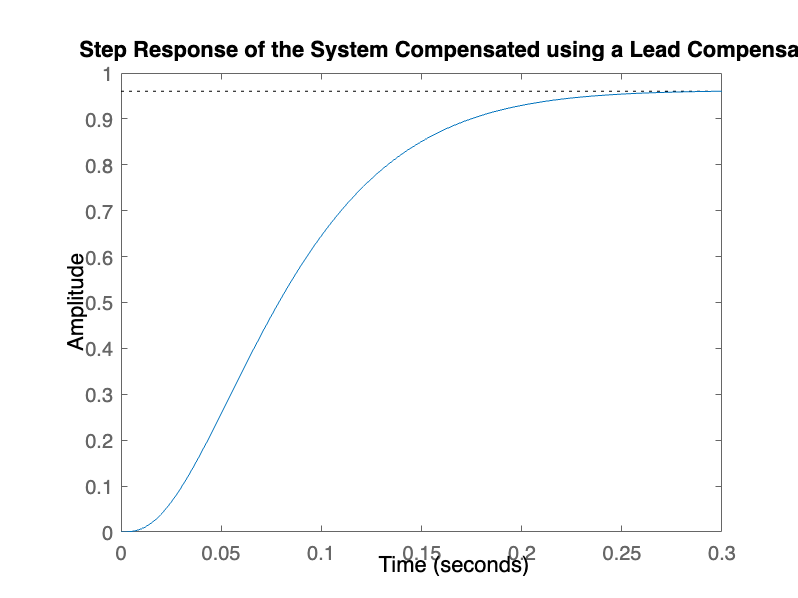


figure (1);
step(positiontfLDC_feedback); title('Step Response of the System Compensated using a Lead Compensator');

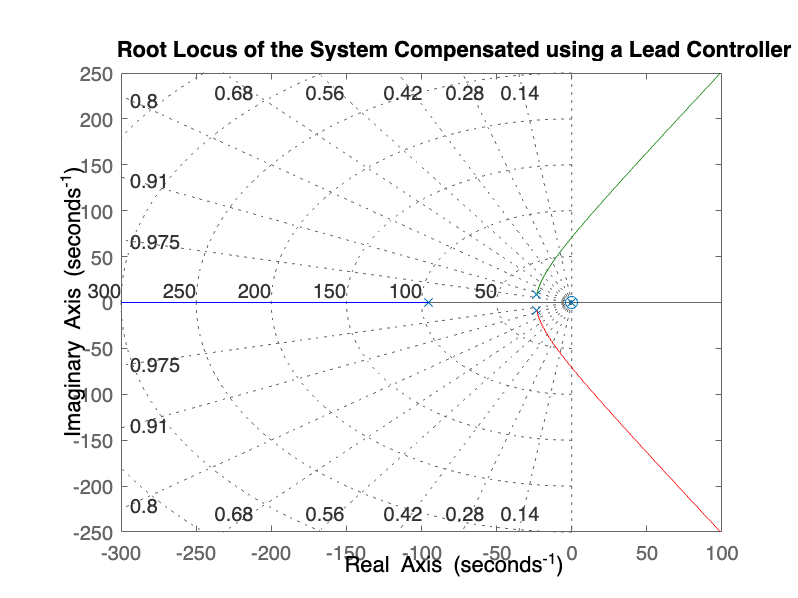

rlocus(positiontfLDC_feedback); grid on; title('Root Locus of the System Compensated using a Lead Controller');

info_motorLDC= stepinfo(positiontfLDC_feedback)

info_motorLDC = struct with fields:
         RiseTime: 0.1258
    TransientTime: 0.2165
     SettlingTime: 0.2165
      SettlingMin: 0.8671
      SettlingMax: 0.9614
        Overshoot: 0.1080
       Undershoot: 0
             Peak: 0.9614
         PeakTime: 0.3555


[out1, t1]= step(positiontfLDC_feedback);
SP= 1;
errorLDC= abs(SP-out1(end))

errorLDC = 0.0399

**== COMMENTS**

From the given step response info: 

- Settling Time= 0.2165 ... satisfied condition (<= 1 second)

- Overshoot= 0.1080% ... satisfied condition (<= 1%)

- Steady-state error= 0.0399...satisfied condition  (<=1)

#### Designing a LAG Compensator 

% From the computed transfer function, Gs_OLTF, the system is a Type 1 system.

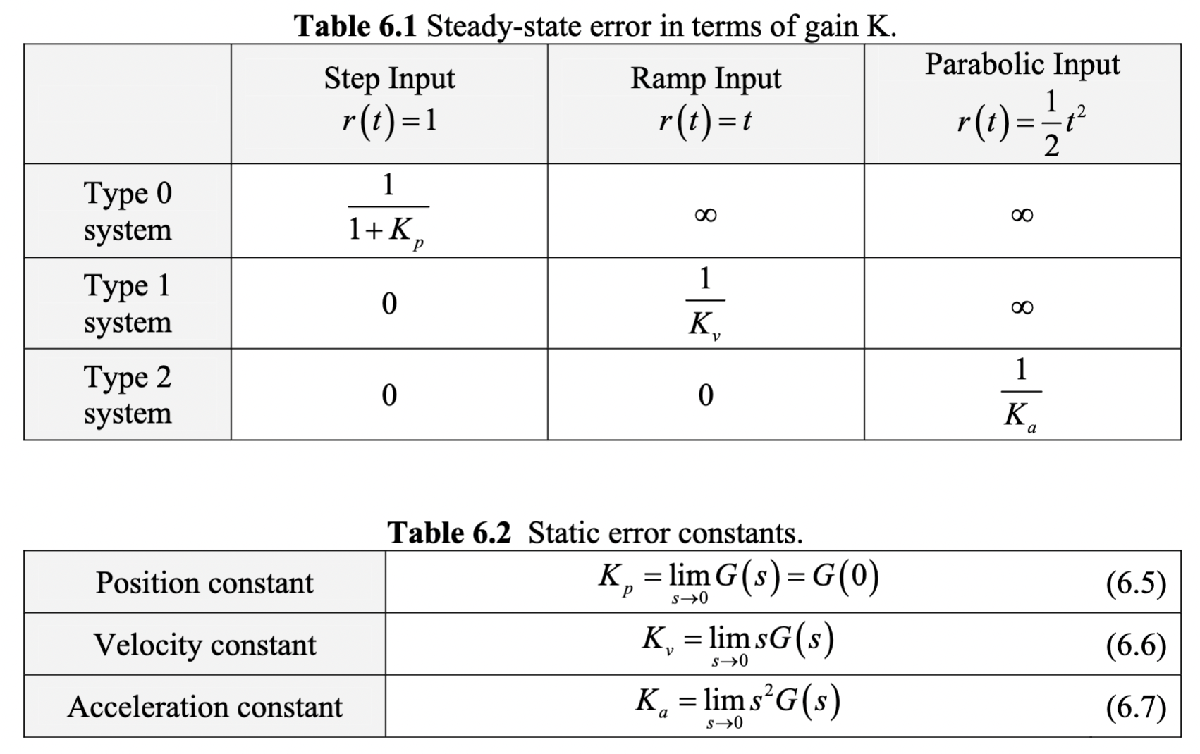

Calculations (formula) for the overall gain, 

$K_{\textrm{overall}} =\frac{1\;}{|G\left(s\right)H\left(s\right)|\;}$, used G(s) is Gs_OLTF, H(s) is lag compensator

% Using the steady state error as the reference, the static error is
% constant is computed as follows. 

Kv= 0.022/0.2404; % s appproaches 0, therefore s=0
elead= 1/Kv;
% Assume a value of Plag close to the origin,
plag= 0.02;
zlag= (elead*plag)/SSE;

% solving for K:
K1= 1/((0.2185/0.02)*(0.022/.2402));

% the given transfer function for a lag compensator is:
num3= K1*[1 zlag];
den3= [1 plag];
LGCtf= tf(num3, den3)

LGCtf =
 
  0.9994 s + 0.2184
  -----------------
      s + 0.02
 
Continuous-time transfer function.




positiontfLGC= LGCtf*Gs_CLTF; % transfer function of the system compensated using a lag controller
positiontfLGC_feedback= feedback(positiontfLGC, 1)

positiontfLGC_feedback =
 
                     0.02199 s + 0.004805
  ----------------------------------------------------------
  0.00775 s^4 + 0.5204 s^3 + 0.2508 s^2 + 0.029 s + 0.004849
 
Continuous-time transfer function.



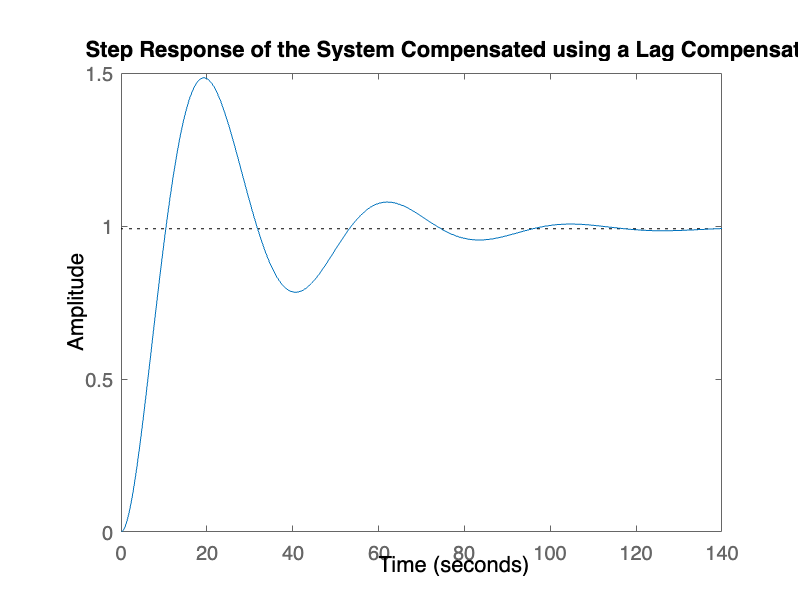


figure (2);
step(positiontfLGC_feedback); title('Step Response of the System Compensated using a Lag Compensator');

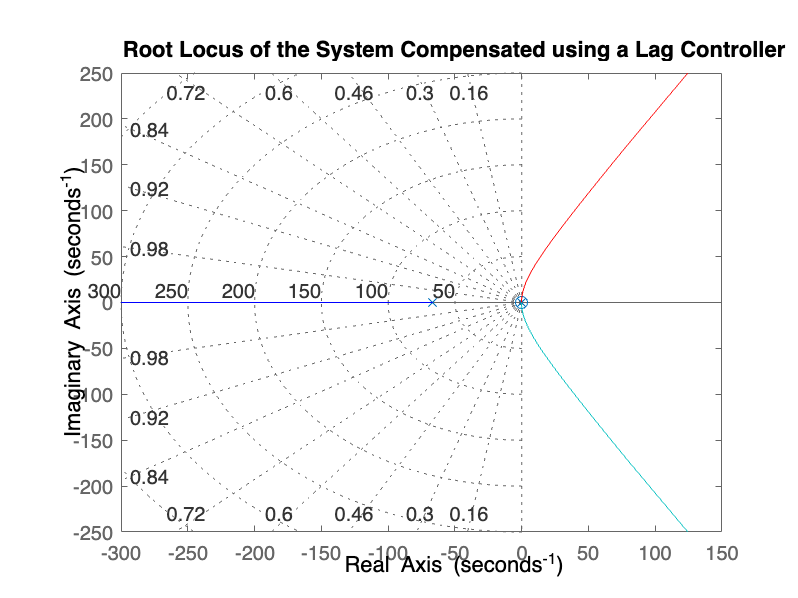

rlocus(positiontfLGC_feedback); grid on; title('Root Locus of the System Compensated using a Lag Controller');

info_motorLGC= stepinfo(positiontfLGC_feedback)

info_motorLGC = struct with fields:
         RiseTime: 7.1385
    TransientTime: 90.6688
     SettlingTime: 90.6688
      SettlingMin: 0.7835
      SettlingMax: 1.4843
        Overshoot: 49.7897
       Undershoot: 0
             Peak: 1.4843
         PeakTime: 19.3981


[out2, t2]= step(positiontfLGC_feedback);
SP= 1;
errorLGC= abs(SP-out2(end))

errorLGC = 0.0105

From the given step response info: 

- Settling Time= 90.6688 ... does not satisfy the condition (<= 1 second)

- Overshoot= 49.7897 ... does not satisfy condition (<= 1%)

- Steady-state error= 0.0105 ...satisfied condition  (<=1)

#### Designing a LEAD-LAG Compensator 

% Cascading the lead and lag compensators, 

numfa= [1 zlead];
numfb= [1 zlag];
denfa= [1 plead];
denfb= [1 plag];
numf= K*K1*conv(numfa,numfb);
denf= conv(denfa, denfb);
LDGCtf= tf(numf, denf) 

LDGCtf =
 
  1.978e04 s^2 + 4504 s + 39.45
  -----------------------------
      s^2 + 74.52 s + 1.49
 
Continuous-time transfer function.




positiontfLDGC= Gs_CLTF*LDGCtf; % transfer function of the system compensated using a lead-lag controller
positiontfLDGC_feedback= feedback(positiontfLDGC, 1)

positiontfLDGC_feedback =
 
                     435.2 s^2 + 99.09 s + 0.8679
  ------------------------------------------------------------------
  0.00775 s^5 + 1.098 s^4 + 39.02 s^3 + 453.9 s^2 + 99.61 s + 0.8712
 
Continuous-time transfer function.



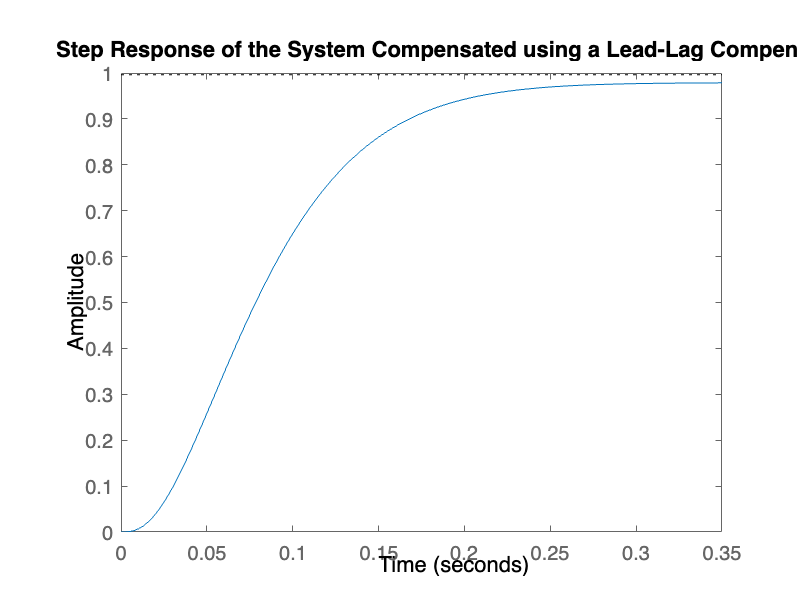


figure (3);
step(positiontfLDGC_feedback); title('Step Response of the System Compensated using a Lead-Lag Compensator');

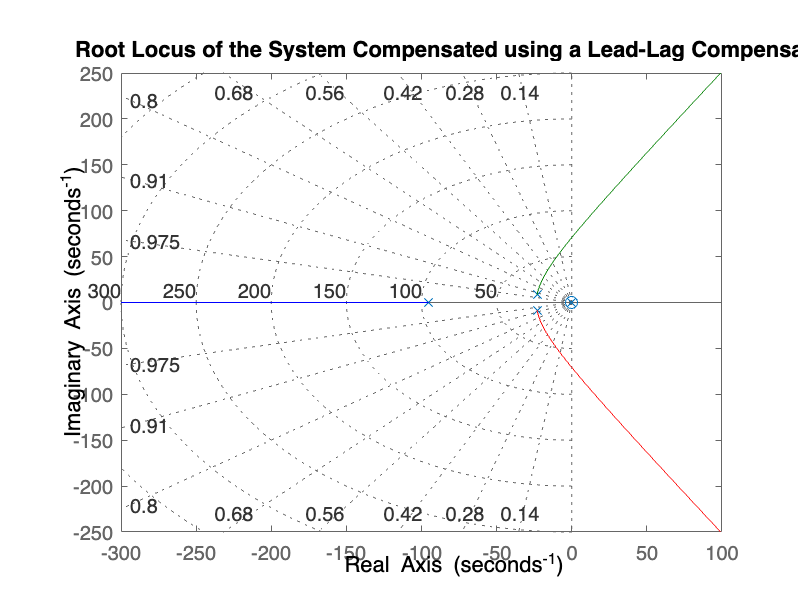

rlocus(positiontfLDGC_feedback); grid on; title('Root Locus of the System Compensated using a Lead-Lag Compensator');

info_motorLDGC= stepinfo(positiontfLDGC_feedback)

info_motorLDGC = struct with fields:
         RiseTime: 0.1357
    TransientTime: 0.2927
     SettlingTime: 0.2927
      SettlingMin: 0.8990
      SettlingMax: 0.9818
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9818
         PeakTime: 1.2935


[out3, t3]= step(positiontfLDGC_feedback);
SP= 1;
errorLDGC= abs(SP-out3(end))

errorLDGC = 0.0216

**== COMMENT:**

From the given step response info: 

- Settling Time= 0.2927 ... satisfied condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 1%)

- Steady-state error= 0.0216 ... satisfied condition (<=1%)

## SPEED CONTROL (ANGULAR VELOCITY OUTPUT)

### TRANSFER FUNCTION

The transfer function is given by the following (motor and arm)

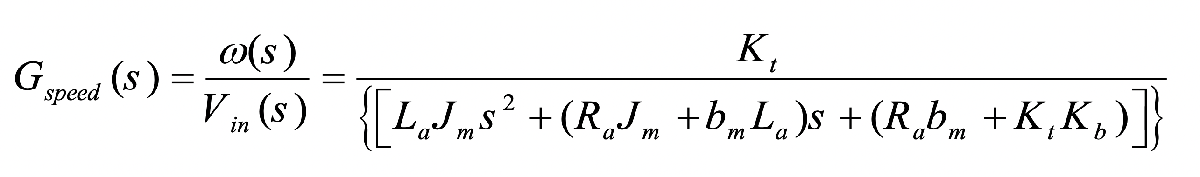

% using the same nominal values,

J = 0.05; 
b = 0.09;
Kb = 0.020;
Kt = 0.022;
Ra = 2; % in ohms
La = 0.03; % in Henry
V = 12; % in volts
M= 10; 
b_arm= 0.03;
L = 0.5; % in m
n= 1;

% calculating Jload given by the formula, (ml^2)/12
Jload= (M*L^2)/12;

% calculating equivalent values
beq= b_arm + b*n;
Jeq= J + Jload*n;

V_max = input(' Enter maximum allowed voltage , V max : ');
Speed_rpm = input( 'Enter rpm of robotic arm : ');

% determining the transfer function [OPEN LOOP] 
num = [Kt*n];
den=[(La*Jeq) (Ra*Jeq+beq*La) (Ra*beq+Kt*Kb)];
disp('Robot arm open loop transfer function, Speed/Volt: ')

Robot arm open loop transfer function, Speed/Volt: 


Gs_OLTF =tf(num,den)

Gs_OLTF =
 
               0.022
  -------------------------------
  0.00775 s^2 + 0.5203 s + 0.2404
 
Continuous-time transfer function.



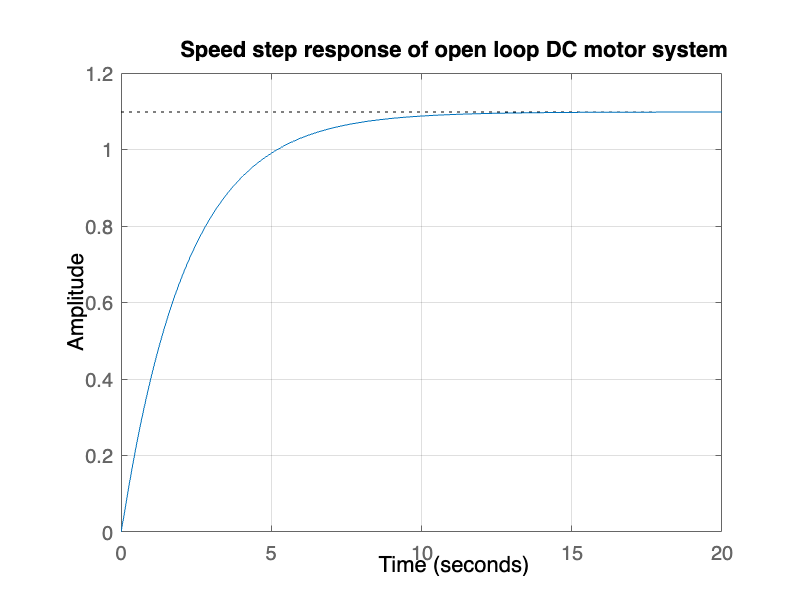

Gs_OLTFa = V*Gs_OLTF;
step(Gs_OLTFa); title('Speed step response of open loop DC motor system'); grid on


% Sensor modelling, Km/Tachometer
Kr =V_max/Speed_rpm; % potentiometer
Gs_CLTF= feedback(Gs_OLTF,(Kr/n))

Gs_CLTF =
 
               0.022
  -------------------------------
  0.00775 s^2 + 0.5203 s + 0.2602
 
Continuous-time transfer function.



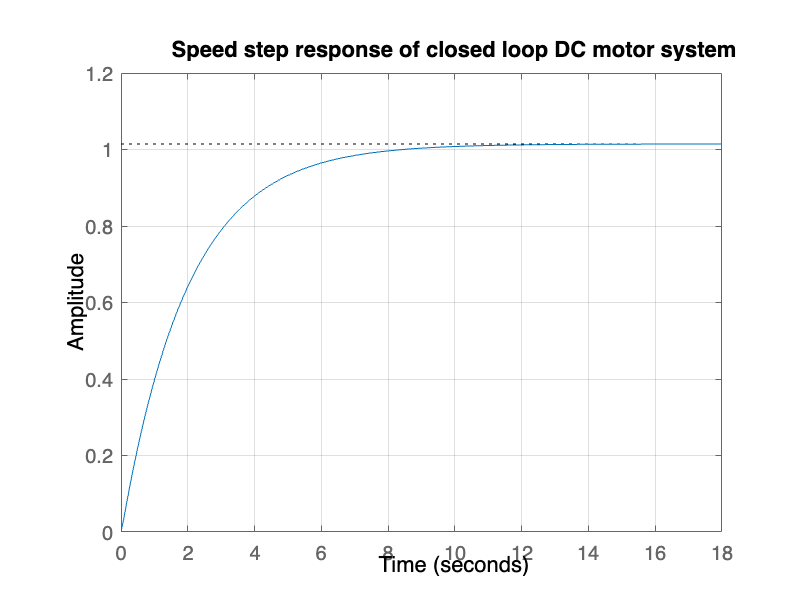

step(V*Gs_CLTF); title('Speed step response of closed loop DC motor system'); grid on


% Getting Initial Time Responses
info_mtr= stepinfo(Gs_CLTF)

info_mtr = struct with fields:
         RiseTime: 4.3594
    TransientTime: 7.7774
     SettlingTime: 7.7774
      SettlingMin: 0.0764
      SettlingMax: 0.0845
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0845
         PeakTime: 20.9248


% getting steady-state error
[out, t]= step(Gs_CLTF);
SP= 1;
error= abs(SP-out(end))

error = 0.9155

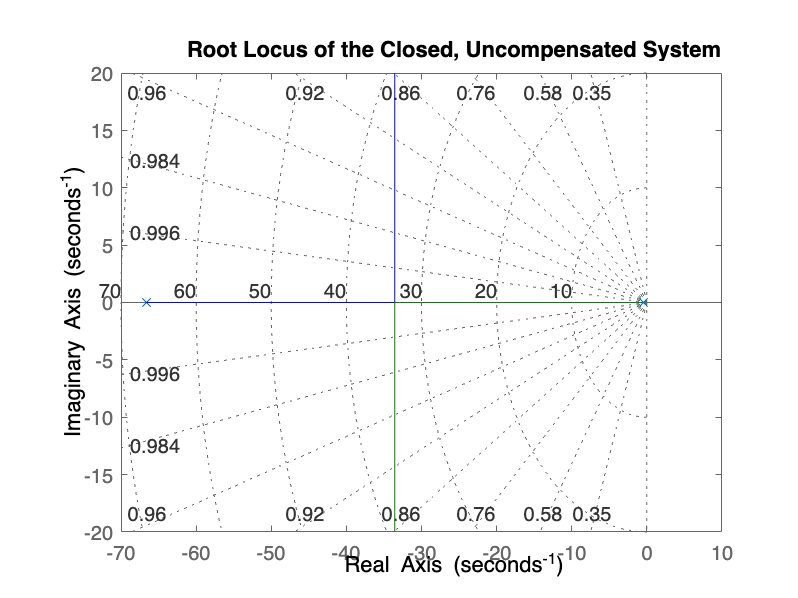


% root locus visualizations
rlocus(Gs_CLTF); grid on; title ('Root Locus of the Closed, Uncompensated System')


dena= [0.00775 0.5203 0.2426]; % getting the precise value of the poles
poles= roots(dena)

poles =   -66.6659
   -0.4696


From the given step response info: 

- Settling Time= 7.7774 ... does not satisfy the condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 1%)

- Steady-state error= 0.9155 ... satisfied condition (<=1%)

== **VISUALIZATION**

Control System Designer

### DETERMINING THE DESIRED POLES

== **DESIGN CRITERIA:**

- Settling Time (Ts) <= 1 second

- % Overshoot <= 1%

- Steady State Error = 1

% ... from the given design criteria:
Ts=1;
PO=0.01;
SSE=1;   

zeta= sqrt(log(PO)^2 /(pi^2 + log(PO)^2)) %Damping ratio

zeta = 0.8261

Wn=4/(Ts*zeta) % Natural frequency 

Wn = 4.8421

Incorporating the parameters, the given transfer function is now:

% Computing for the desired poles:
num1= [(Wn)^2];
den1= [1 2*zeta*Wn (Wn)^2];
poles= roots(den1)

poles =   -4.0000 + 2.7288i
  -4.0000 - 2.7288i


**== COMMENT **

Therefore, $S_{1,2\;} =-4\pm 4\ldotp 1948j$ are the desired poles. 

### DESIGNING THE COMPENSATORS  

#### Designing a LEAD Compensator 

% From the poles in the system and shown in the root locus, place a zero to
% cancel the rightmost pole, P2= -0.4696

zlead= 0.4696

zlead = 0.4696

Calculations (formula) for Plead:


$$\Sigma \theta_z -\Sigma \theta_p =-180$$


θ3 - (θ1+θ2+θ4)= -180

Calculations (formula) for the overall gain, 


$$K_{\textrm{overall}} =\frac{\textrm{L1}\;\textrm{L2}\;\textrm{L4}}{\textrm{L3}}$$


% calculating for the angles
theta1= 180- rad2deg(atan(2.7288/(4-0.4696)))

theta1 = 142.2980

theta2= rad2deg(atan(2.7288/(66.6659-4)))

theta2 = 2.4934

theta3= rad2deg(atan(2.7288/(4-0.4696)))

theta3 = 37.7020

syms x plead
theta4= rad2deg(atan(2.7288/(plead-4)))

$$theta4 = \frac{180\,\mathrm{atan}\left(\frac{3411}{1250\,\left(\mathrm{plead}-4\right)}\right)}{\pi }$$


% solve for plead
te= theta3-(theta1+theta2);
eq= 180+te

eq = 72.9106

eqn = rad2deg(atan(2.7288/(x-4))) == 72.6716;
solve(eqn, x);
eqn = rad2deg(tan(atan(2.7288/(x-4)))) == tan(72.6716);
solve(eqn, x);
double(ans)

ans = 358.8930


plead= 358.8930;

% Solving for K;
L1= sqrt((2.7288)^2+(4-0.4696)^2);
L2= sqrt((2.7288)^2+(66.66594-4)^2);
L4= sqrt((2.7288)^2+(plead-4)^2);
L3= sqrt((2.7288)^2+(4-0.4696)^2);
K= (L1*L2*L4)/L3;

% the given transfer function for a lead compensator is:
num2= K*[1 zlead];
den2= [1 plead];
LDCtf= tf(num2, den2)

LDCtf =
 
  2.226e04 s + 1.045e04
  ---------------------
        s + 358.9
 
Continuous-time transfer function.




speedtfLDC= LDCtf*Gs_CLTF % transfer function of the system compensated using a lead controller

speedtfLDC =
 
              489.8 s + 230
  --------------------------------------
  0.00775 s^3 + 3.302 s^2 + 187 s + 93.4
 
Continuous-time transfer function.



speedtfLDC_feedback= feedback(speedtfLDC,1)

speedtfLDC_feedback =
 
                489.8 s + 230
  -----------------------------------------
  0.00775 s^3 + 3.302 s^2 + 676.7 s + 323.4
 
Continuous-time transfer function.



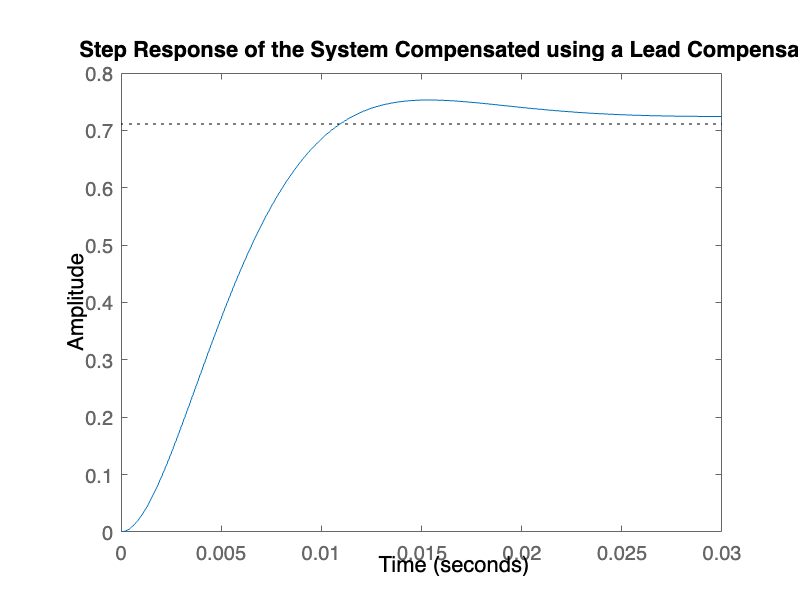


figure (1);
step(speedtfLDC_feedback); title('Step Response of the System Compensated using a Lead Compensator');

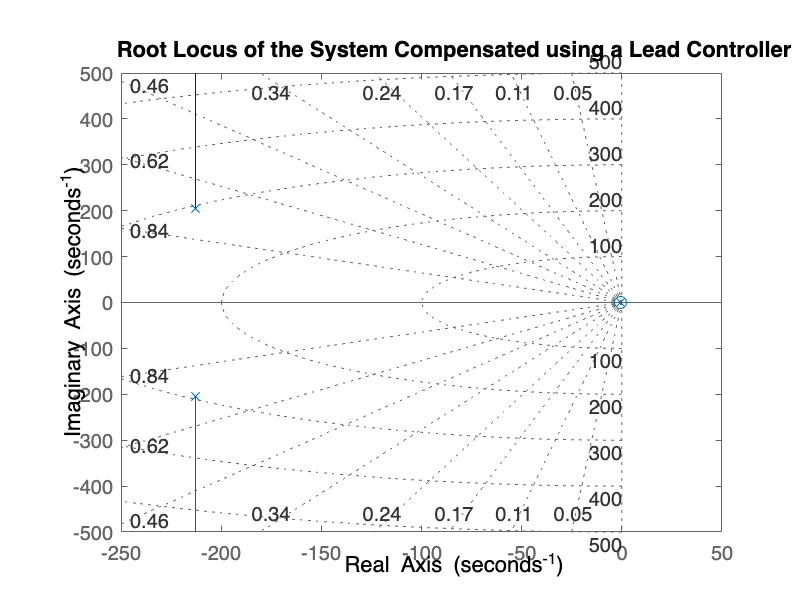

rlocus(speedtfLDC_feedback); grid on; title('Root Locus of the System Compensated using a Lead Controller');

info_motorLDC= stepinfo(speedtfLDC_feedback)

info_motorLDC = struct with fields:
         RiseTime: 0.0072
    TransientTime: 0.0267
     SettlingTime: 0.0267
      SettlingMin: 0.6411
      SettlingMax: 0.7530
        Overshoot: 5.8733
       Undershoot: 0
             Peak: 0.7530
         PeakTime: 0.0154


[out1, t1]= step(speedtfLDC_feedback);
SP= 1;
errorLDC= abs(SP-out1(end))

errorLDC = 0.2750

**== COMMENTS**

From the given step response info: 

- Settling Time= 0.0267 ...  satisfied  condition (<= 1 second)

- Overshoot= 5.8733 ... does not satisfy the condition (<= 1%)

- Steady-state error= 0.2750 ...satisfied condition  (<=1)

#### Designing a LAG Compensator 

% From the computed transfer function, motortf, the system is a Type 1 system.

% Using the steady state error as the reference, the static error is
% constant is computed as follows. 

Kv= 0.022/0.2426; % s appproaches 0, therefore s=0
elead= 1/Kv;
% Assume a value of Plag close to the origin,
plag= 2;
zlag= (elead*plag)/SSE;

% solving for K:
K1= 1/((zlag/plag)*(0.022/.2426));

% the given transfer function for a lag compensator is:
num3= K1*[1 zlag];
den3= [1 plag];
LGCtf= tf(num3, den3)

LGCtf =
 
  s + 22.05
  ---------
    s + 2
 
Continuous-time transfer function.




speedtfLDC= LGCtf*Gs_CLTF % transfer function of the system compensated using a lag controller

speedtfLDC =
 
               0.022 s + 0.4852
  -------------------------------------------
  0.00775 s^3 + 0.5358 s^2 + 1.301 s + 0.5205
 
Continuous-time transfer function.



speedtfLDC_feedback= feedback(speedtfLDC, 1)

speedtfLDC_feedback =
 
               0.022 s + 0.4852
  ------------------------------------------
  0.00775 s^3 + 0.5358 s^2 + 1.323 s + 1.006
 
Continuous-time transfer function.



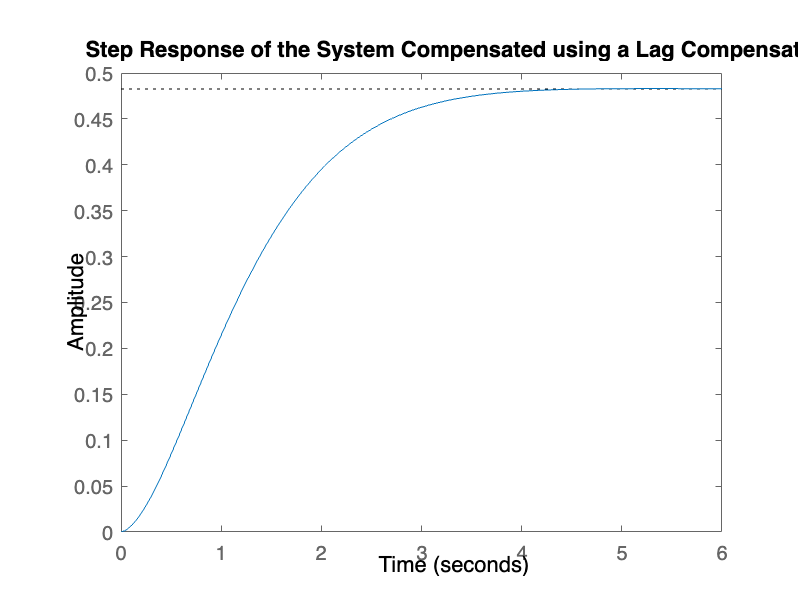


figure (2);
step(speedtfLDC_feedback); title('Step Response of the System Compensated using a Lag Compensator');

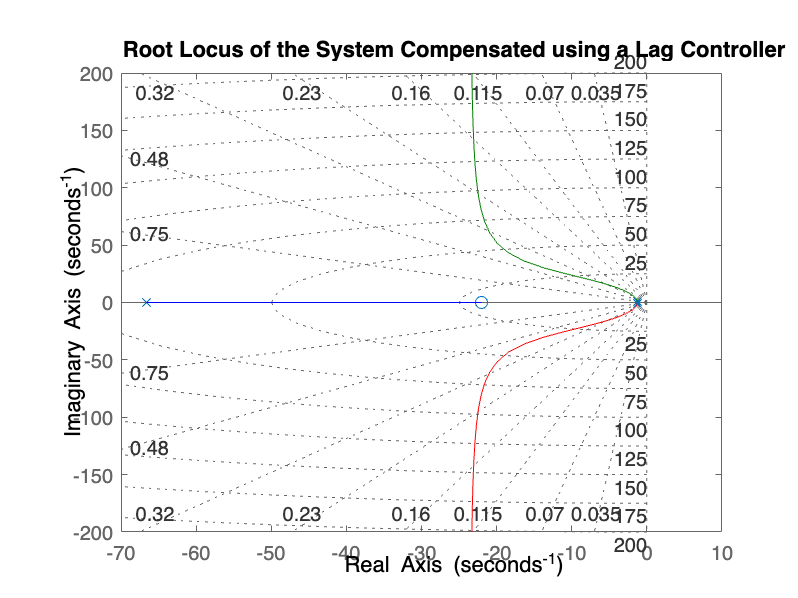

rlocus(speedtfLDC_feedback); grid on; title('Root Locus of the System Compensated using a Lag Controller');

info_motorLGC= stepinfo(speedtfLDC_feedback)

info_motorLGC = struct with fields:
         RiseTime: 2.0874
    TransientTime: 3.3941
     SettlingTime: 3.3941
      SettlingMin: 0.4344
      SettlingMax: 0.4830
        Overshoot: 0.1129
       Undershoot: 0
             Peak: 0.4830
         PeakTime: 5.3438


[out2, t2]= step(speedtfLDC_feedback);
SP= 1;
errorLGC= abs(SP-out2(end))

errorLGC = 0.5171

From the given step response info: 

- Settling Time= 3.3941 ... does not satisfy the condition (<= 1 second)

- Overshoot= 0.1129 ... satisfied condition (<= 1%)

- Steady-state error= 0.5171 ...satisfied condition  (<=1)

#### Designing a LEAD-LAG Compensator 

% Cascading the lead and lag compensators, 

numfa= [1 zlead];
numfb= [1 zlag];
denfa= [1 plead];
denfb= [1 plag];
numf= K*K1*conv(numfa,numfb);
denf= conv(denfa, denfb);
LDGCtf= tf(numf, denf) 

LDGCtf =
 
  2.226e04 s^2 + 5.014e05 s + 2.306e05
  ------------------------------------
         s^2 + 360.9 s + 717.8
 
Continuous-time transfer function.




speedtfLDGC= Gs_CLTF*LDGCtf; % transfer function of the system compensated using a lead-lag controller
speedtfLDGC_feedback= feedback(speedtfLDGC, 1)

speedtfLDGC_feedback =
 
              489.8 s^2 + 1.103e04 s + 5072
  ------------------------------------------------------
  0.00775 s^4 + 3.317 s^3 + 683.3 s^2 + 1.15e04 s + 5259
 
Continuous-time transfer function.



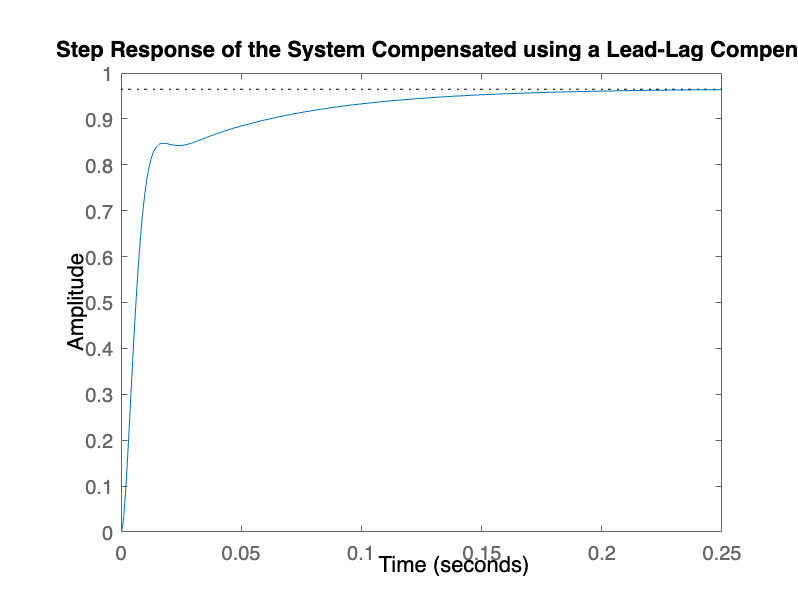


figure (3);
step(speedtfLDGC_feedback); title('Step Response of the System Compensated using a Lead-Lag Compensator');

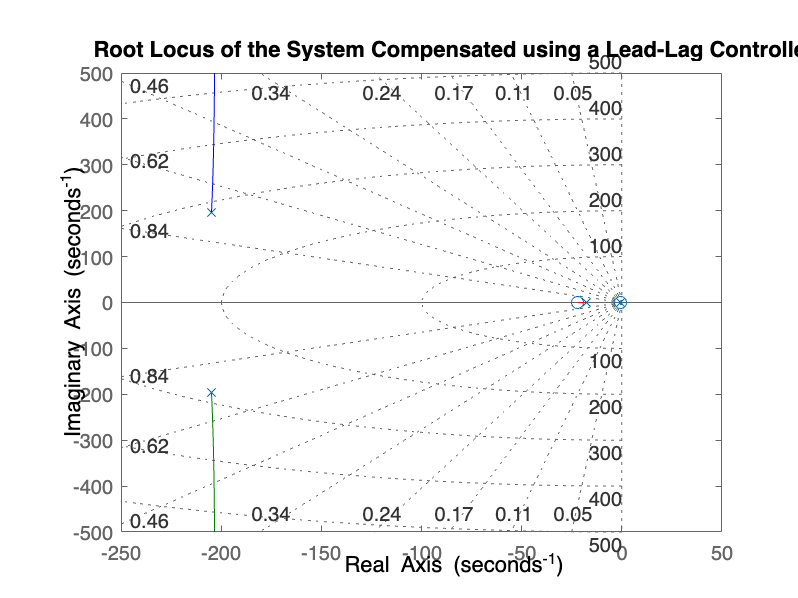

rlocus(speedtfLDGC_feedback); grid on; title('Root Locus of the System Compensated using a Lead-Lag Controller');

info_motorLDGC= stepinfo(speedtfLDGC_feedback)

info_motorLDGC = struct with fields:
         RiseTime: 0.0379
    TransientTime: 0.1260
     SettlingTime: 0.1260
      SettlingMin: 0.8683
      SettlingMax: 0.9639
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9639
         PeakTime: 0.2514


[out3, t3]= step(speedtfLDGC_feedback);
SP= 1;
errorLDGC= abs(SP-out3(end))

errorLDGC = 0.0380

**== COMMENT:**

From the given step response info: 

- Settling Time= 0.1260 ... satisfied condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.0380... satisfied condition (<=1%)